%https://www.mathworks.com/help/matlab/ref/fft.html

%variables
Fs = 1000; % Sampling frequency                  
T = 1/Fs;                    
L = 8000; % signal length
t = (0:L-1)*T; % Time
%t= 0:0.001:8


%Task i) plotting v(t)

v_t = abs(sin(pi*t)) + 2*sin(3*pi*t) + 3*sin(6*pi*t)

v_t =          0    0.0785    0.1571    0.2355    0.3139    0.3922    0.4705    0.5485    0.6265    0.7042    0.7818    0.8591    0.9362    1.0131    1.0896    1.1659    1.2418    1.3174    1.3926    1.4675    1.5419    1.6159    1.6895    1.7626    1.8352    1.9073    1.9789    2.0499    2.1204    2.1903    2.2596    2.3282    2.3963    2.4636    2.5303    2.5963    2.6616    2.7261    2.7899    2.8530    2.9152    2.9767    3.0373    3.0972    3.1561    3.2143    3.2715    3.3279    3.3833    3.4379


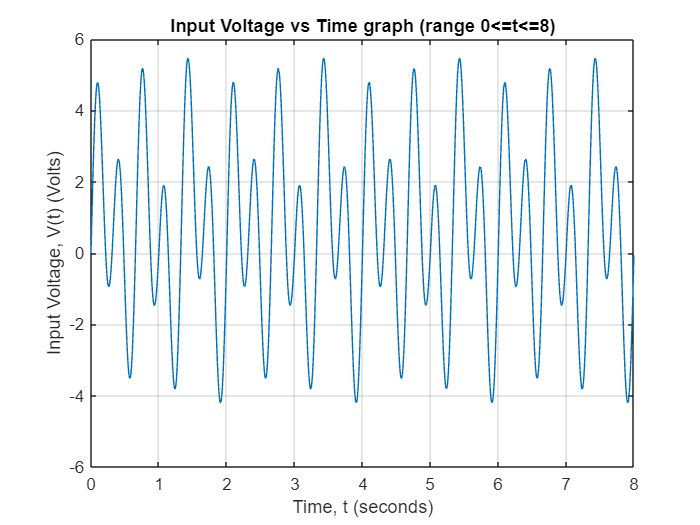

plot(t,v_t)
xlabel('Time, t (seconds)')
ylabel('Input Voltage, V(t) (Volts)')
grid on
title('Input Voltage vs Time graph (range 0<=t<=8)')


%task ii) plot amplitude-frequency response of v(t)

v_f = fft(v_t) %fast fourier transform

v_f = 1.0e+04 *

   0.5093 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.1698 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.8000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0340 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0146 - 1.2000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0081 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0051 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0036 + 0.0000i   0.0000 - 0.0000i


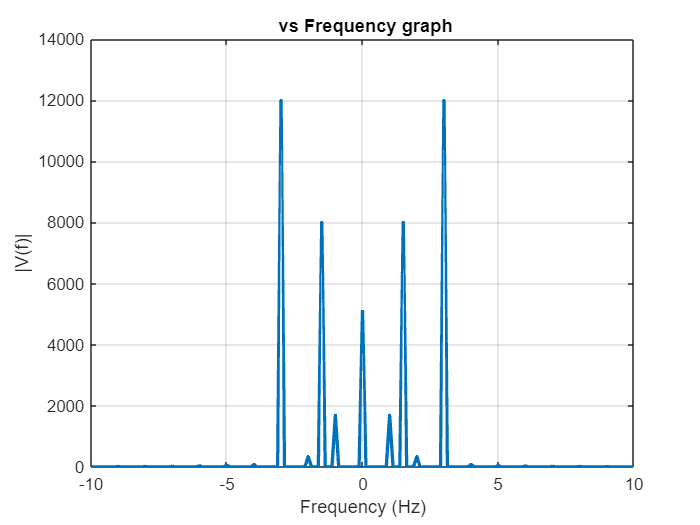


plot((-L/2:(L/2-1))*Fs/(L-1),fftshift(abs(v_f)),"LineWidth",2) %vectors of same length
xlabel('Frequency (Hz)')
ylabel('|V(f)|')
grid on
title(' vs Frequency graph')
xlim([-10 10]) %limiting x axis to make data readable






%task iii) plot amplitude-frequency response of circuit

circuit = tf([2],[0.1 1.1 3])

circuit =
 
           2
  -------------------
  0.1 s^2 + 1.1 s + 3
 
Continuous-time transfer function.
Model Properties


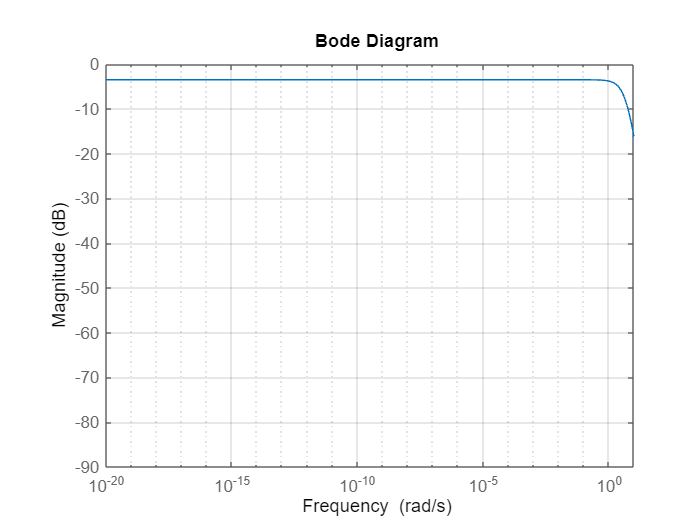

bodemag(circuit)
grid on
xlim([-10 10])


%task iv) plot v,oltage accross R2 (t=0 to t=infty)
lsim(circuit, v_t, t)

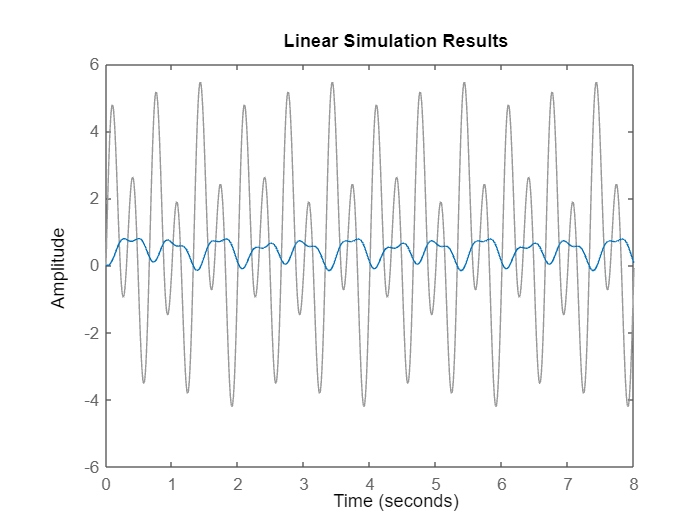

xlim([0 8])


%task iv) plot voltage accross R2 (t=0 to t=4, then stops)
v_t_0to4 = v_t.*heaviside(t) - v_t.*heaviside(t-4)

v_t_0to4 =          0    0.0785    0.1571    0.2355    0.3139    0.3922    0.4705    0.5485    0.6265    0.7042    0.7818    0.8591    0.9362    1.0131    1.0896    1.1659    1.2418    1.3174    1.3926    1.4675    1.5419    1.6159    1.6895    1.7626    1.8352    1.9073    1.9789    2.0499    2.1204    2.1903    2.2596    2.3282    2.3963    2.4636    2.5303    2.5963    2.6616    2.7261    2.7899    2.8530    2.9152    2.9767    3.0373    3.0972    3.1561    3.2143    3.2715    3.3279    3.3833    3.4379


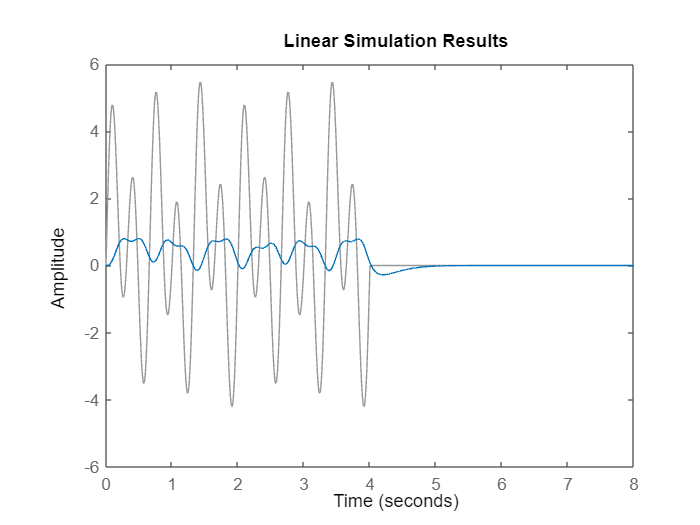

lsim(circuit, v_t_0to4,t)
xlim([0 8])